# Part II: Introduction to Battery Modelling with BattMo

**Dr. Sridevi Krishnamurthi **and** Dr. Simon Clark, ***SINTEF AS, Battery Technology, Trondheim, Norway*

In part 1 of the modeling guide, we provided an overview of battery modeling, introduced key terms, and explained how to use BattMo. In part 2, we will delve into the DFN model in detail, the model employs physical, chemical, and electrochemical parameters to describe the behavior of the electrodes and electrolytes, with each of these parameters potentially affecting the cell's capacity and performance. 

## 1. DFN Model 

Physics based battery modeling encompasses various levels of complexity, ranging from microscale models that detail individual electrode particles to single-particle models (SPM) that approximate the entire electrode as a single homogeneous particle. 

The Doyle-Fuller-Newman (DFN) model also called pseudo-two-dimensional (P2D) lies between these two approaches. While it lacks the fine spatial resolution of microscale models, which describe the three-dimensional microstructure, the DFN model assumes spherical symmetry for the active particles and characterizes the microstructure using a few key parameters, significantly reducing computational demands. 

For a more detailed overview of the different models, please refer [here](https://iopscience.iop.org/article/10.1088/2516-1083/ac7d31/meta).

Let us look at the equations of the model,

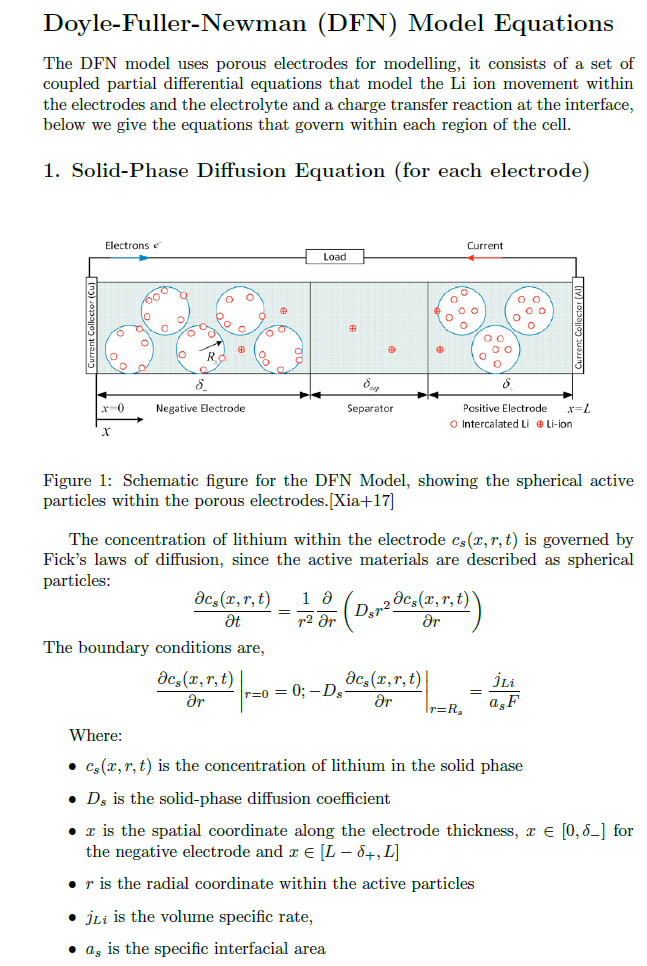

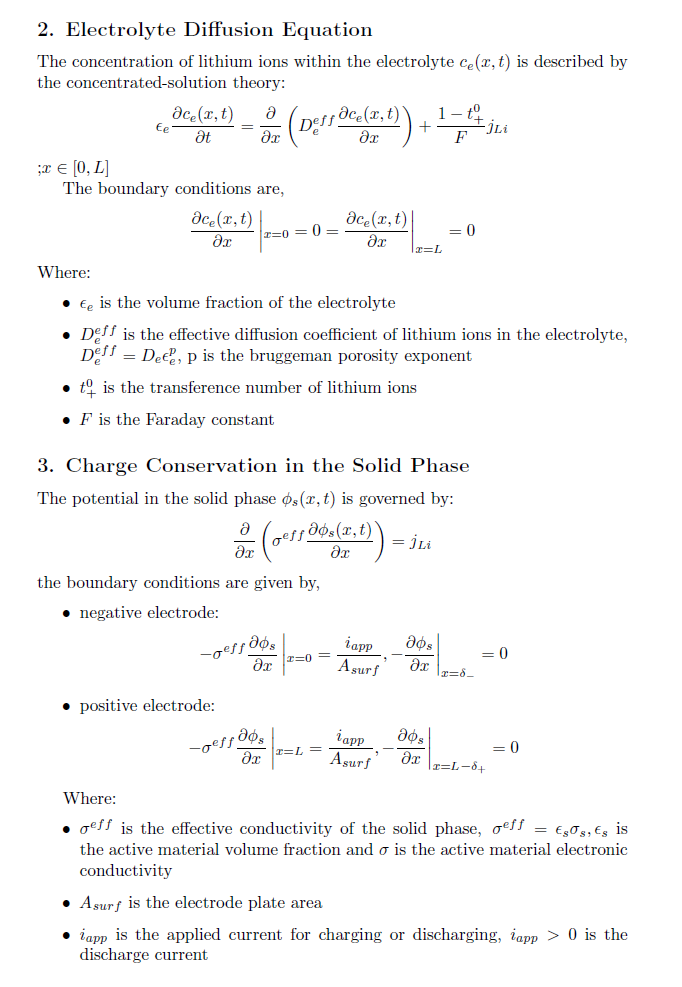

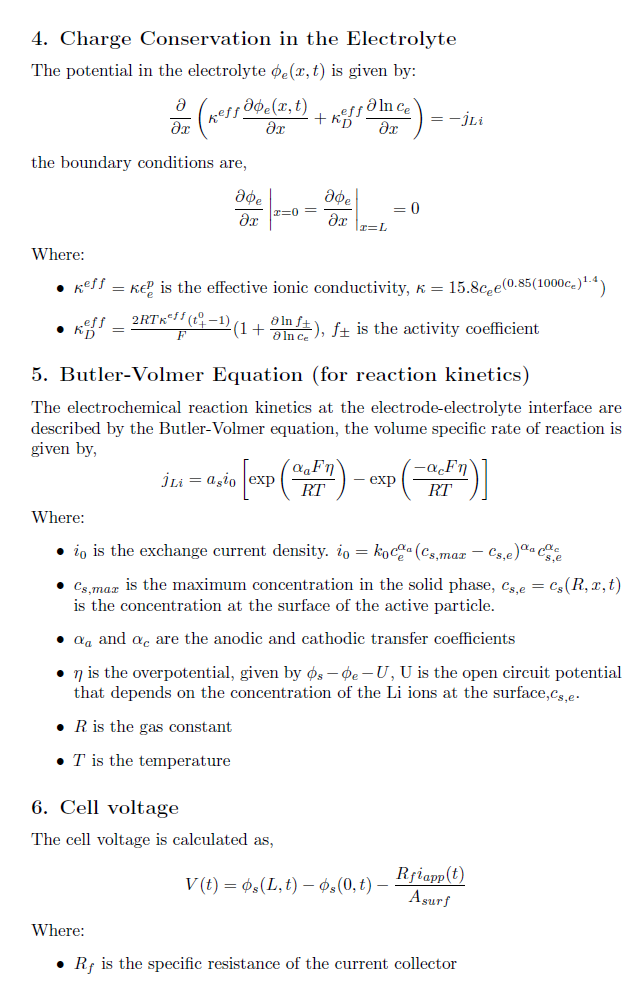

As illustrated in the model equations, there are a bunch of different parameters that affect the over all ell 

## **2. Overpotentials and Voltage losses**

The cell potential observed during operation differs from the thermodynamic potential, known as the Open Circuit Voltage (OCV), due to various losses that occur when a current is flowing. The additional voltage required to drive the charging and discharging at a given current is called the cell overpotential or overvoltage. This overvoltage arises from several factors, including ohmic losses, kinetic limitations, and transport limitations, each contributing to the overall voltage drop observed during cell operation, see **Figure 2** .

In this tutorial, we will vary the different parameters that contribute to each of these factors and examine their effects on the overall kinetics and performance of the cell. By adjusting variables such as reaction rate constants, charge transfer coefficients, and material parameters such as particle radius and electronic conductivities, we will observe how these changes influence the overpotential and capacities, providing insights into the underlying mechanisms governing electrochemical behavior.

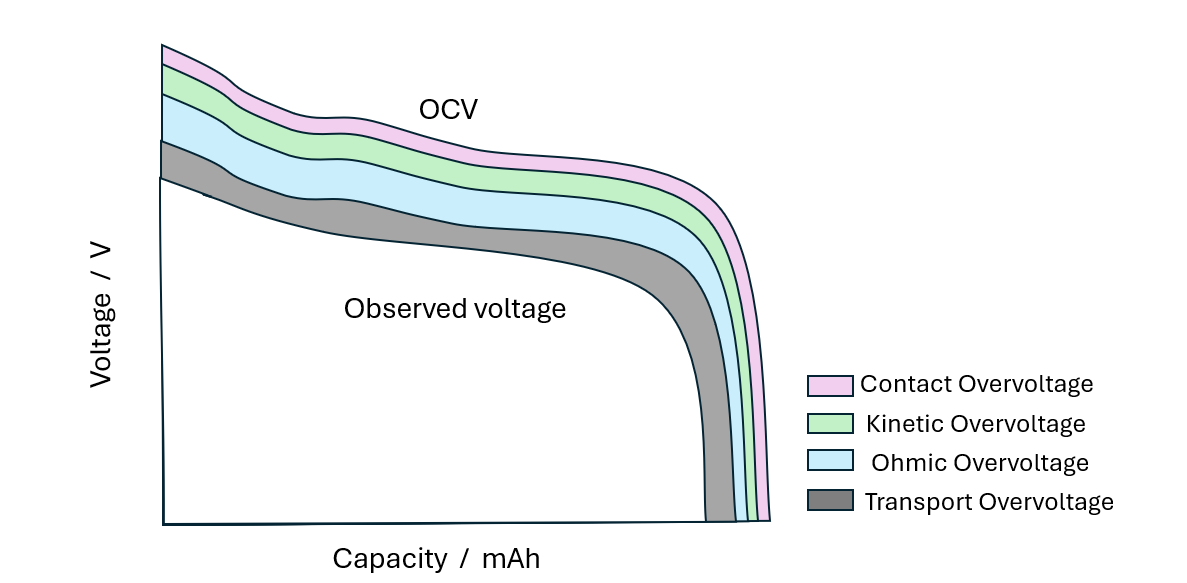

**Figure 2: Schematic breakdown of overpotentials in a lithium-ion battery (LIB) cell. **

** a. Kinetic**

The Butler-Volmer equation describes the kinetics of the charge transfer reaction at the electrode/electrolyte interface and the associated overpotential, as shown above. The rate of the reaction depends on the exchange current density, which is influenced by reaction rate constants, charge transfer coefficients that describe the asymmetry between the forward and backward reactions, and the charge transfer activation energy. These factors collectively determine how efficiently the electrochemical reaction proceeds and how the overpotential varies with current. 

**b. Transport**

Transport limitations, or mass transport limitations, occur due to inefficient diffusion processes, creating resistance to the movement of ions within the electrolyte or electrode materials. Key parameters influencing these limitations include diffusion coefficients and the initial concentrations of reactants. These limitations arise when the delivery rate of reactants to the reaction sites is slower than the rate at which they are consumed by the electrochemical reactions. This resistance to mass transport can lead to the formation of concentration gradients, increased overpotential, and ultimately reduced performance of the cell.

** c. Ohmic and contact**

Ohmic losses occur due to the electronic resistance within the electrodes, the ionic resistance in the electrolyte, and the interfacial resistance between the electrode and the current collectors. The ionic and electronic conductivities significantly influence the overall impedance of the system. These losses contribute to the overall voltage drop and are affected by the C-rate and the temperature of operation.

#### **Example 1. OCV curve and voltage loss at different C-rates**

Thermodynamics determines the open-circuit voltage (OCV) of a cell, and to simulate OCV conditions, a very small C-rate can be employed. As the charging/discharging rate, or C-rate, increases, the cell experiences more pronounced capacity and voltage losses, as illustrated in the following example. At low C-rates, the cell potential closely mirrors the OCV, which is defined by the difference between the OCVs of the positive and negative electrodes. However, as the C-rate rises, the kinetic (activation polarization) and transport (concentration polarization) overpotentials increase nonlinearly, following the model equations discussed earlier.

To further explore this behavior, we discharged our NMC-graphite cell at C-rates ranging from 0.1C to 3C and observe that the potential drop became more significant with higher rates. At the highest rate of 3C, the cell capacity showed the most substantial drop, as expected. The **`plot_capacities`** function processes the parameter array and parameter name, discharging the cell at a constant current (CC) to generate the corresponding voltage vs. capacity plots.

crate_array=[linspace(0.1,3,6)];
crate="Control.CRate";
plot_capacities(crate_array,crate)

### 3. Thermodynamic parameters

The thermodynamic or equilibrium potential, also known as the Open Circuit Voltage (OCV), depends on the nature of the chemical species involved, their concentrations, the State of Charge (SOC), and the temperature. The Nernst equation describes this relationship,

$E = E^\circ - \frac{RT}{nF} \ln Q


$, 

Where:

- E  is the cell potential under non-standard conditions.

- E∘ is the standard cell potential, measured under standard conditions (1 M concentration, 1 atm pressure, and 25°C).

- R is the universal gas constant

- T is the temperature in Kelvin.

- n is the number of moles of electrons transferred in the electrochemical reaction.

- F is the Faraday constant, 

- $Q = \frac{[LiC_6][CoO_2]}{[C_6][LiCoO_2]}
$ is the reaction quotient, which is the ratio of the concentrations of the products to the reactants, each raised to the power of their stoichiometric coefficients.

To study the effect of concentration on the potential, we begin by selecting a very small C-rate of 0.05C and explore how increasing the amount of active material, specifically the lithium content, impacts the cell's potential. This is achieved by increasing the mass fraction of the active material while simultaneously reducing the binder content.

While increasing the mass fraction of active material results in higher capacity due to the greater availability of electrochemically active species, reducing the binder content excessively can lead to structural instabilities within the cell. Therefore, it is crucial to maintain an optimal ratio of binder to active material to prevent structural instability. 

#### **Example 2. Mass** fraction of active material and binder in electrode

electrode_mf="PositiveElectrode.";
Crate_mf=0.05;
ele_mf=[linspace(0.90,0.96,4)];
negative_binder_mf=0.97-ele_mf;
positive_binder_mf=0.975-ele_mf;
markers={'-',"o","x","+",};
output = cell(size(ele_mf));
therm_parameter_1=strcat(electrode_mf,"Coating.ActiveMaterial.massFraction");
therm_parameter_2=strcat(electrode_mf,"Coating.Binder.massFraction");
jsonstruct_default = parseBattmoJson('Examples/JsonDataFiles/sample_input.json');
cccv_control_protocol = parseBattmoJson('cccv_control_charge.json');%loads the CCCV protocol
jsonstruct_modified = mergeJsonStructs({cccv_control_protocol, jsonstruct_default});

parameter Control.controlPolicy is assigned twice with different values. we use the value from first jsonstruct.
parameter Control.lowerCutoffVoltage is assigned twice with different values. we use the value from first jsonstruct.
parameter SOC is assigned twice with different values. we use the value from first jsonstruct.


% instantiate an empty figure
figure()
% use a for-loop to iterate through the vector of mass fraction of active materials
for i = 1:numel(ele_mf)
        jsonstruct_modified.Control.CRate=Crate_mf;
        c1 = split(therm_parameter_1,'.');
        c2=  split(therm_parameter_2,'.');
        jsonstruct_modified = setfield(jsonstruct_modified,c1{:},ele_mf(i)); % active material massfraction
        if strcmp(c1{1}, 'PositiveElectrode')
            jsonstruct_modified = setfield(jsonstruct_modified,c2{:},positive_binder_mf(i));% binder massfraction
        else
            jsonstruct_modified = setfield(jsonstruct_modified,c2{:},negative_binder_mf(i)); % binder massfraction
        end
        jsonstruct_modified.TimeStepping.totalTime = (1./jsonstruct_modified.Control.CRate) .* 3600 .* 1.2;
        % Run the simulation and store the results in the output cell array
        [results,output{i}] = evalc("runBatteryJson(jsonstruct_modified)");        
        % Retrieve the states from the simulation result
        states = output{i}.states;
        % Extract time and voltage quantities
        time = cellfun(@(state) state.time, states);
        voltage = cellfun(@(state) state.('Control').E, states);
        current = cellfun(@(state) state.('Control').I, states);
        % Calculate the capacity
        capacity = time .* current;
        if any(capacity>0)
        start_index_current_pos=find(current >= 0, 1);
        time_discharge=time(start_index_current_pos);
        discharge_capacity = (time-time_discharge) .* current;
        start_index = find(discharge_capacity == 0, 1);
        end_index = find(discharge_capacity > 0, 1,"last");
        plot(discharge_capacity(start_index:end_index)/(hour*milli),voltage(start_index:end_index), markers{i}, 'linewidth', 3)
        else
            plot(capacity/(hour*milli),voltage) 
        end
        L{i} = strcat(num2str(ele_mf(i)));
        legend(L);
    hold on
end

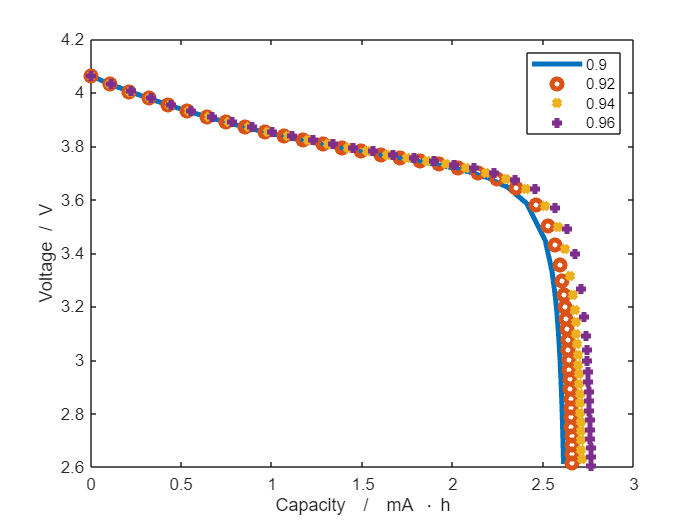


hold off
xlabel('Capacity  /  mA \cdot h')
ylabel('Voltage  /  V')

#### Example 3. Temperature

We now examine the effect of temperature. For a C-rate of 0.05C, across a temperature range from -50°C to 50°C, there is little change in capacity or voltage profile. However, at a higher C-rate, we observe an elevated voltage profile with increasing temperature, which could be attributed to kinetic and transport effects. These effects, which we will study further below, may explain the variations in performance under different temperature conditions and higher current loads.

Crate_temp=0.5;
therm_parameter_3="initT";
therm_parameter_3_vals=[linspace(223,323,5)];
plot_capacities(therm_parameter_3_vals,therm_parameter_3,Crate_temp);

#### Example 4. Saturation concentration of the material

Another approach to increasing concentration is by raising the saturation concentration of Li ions in the host material. This leads to a significant increase in cell capacity, but only up to a certain point, after which the capacity is limited by the other electrode's (negative) capacity. It should be mentioned that modifying the saturation concentration, changes inherently alters the material's intrinsic properties, potentially impacting the stability of the electrode structure.

electrode_cmax="PositiveElectrode.";
Crate_cmax=0.05;
therm_parameter_3=strcat(electrode_cmax,"Coating.ActiveMaterial.Interface.saturationConcentration");
therm_parameter_3_vals=[linspace(30555,80555,5)];
plot_capacities(therm_parameter_3_vals,therm_parameter_3,Crate_cmax);

### 4. Kinetic parameters

The charge transfer at the interface between the electrolyte and electrode is governed by the Butler-Volmer equation. The butler-volmer equation describes the current (reaction rate) as a function of the overpotential and charge transfer co-efficients at the interface. We will assume that mass transfer (transport) limitations are minimal, meaning that the movement of ions from the bulk solution to the electrode interface is faster than the rate at which they are consumed at the interface. This assumption allows us to focus on the reaction kinetics at the interface without being significantly influenced by concentration gradients or diffusion limitations in the electrolyte.

We now look at the various parameters affecting the kinetics of the reaction starting with the activation energy of the reaction,

#### **Example 5. **Activation energy of reaction at the surface of the active particles $E_a$- Butler Volmer equation

electrode_Ea="PositiveElectrode.";
crate_Ea=3;
kinetic_parameter_4=strcat(electrode_Ea,"Coating.ActiveMaterial.Interface.activationEnergyOfReaction");% does not seem to affect the discharge profile
kinetic_parameter_4_vals=[linspace(20,70000,5)];
plot_capacities(kinetic_parameter_4_vals,kinetic_parameter_4,crate_Ea)

#### **Example 6. **Charge transfer coefficient (anodic and cathodic) at the surface of the active particles - Butler Volmer equation

Typically, the charge transfer coefficient is assumed to be 0.5, indicating a symmetric process where the forward and backward reaction rates (charge and discharge) are equally favorable. However, an asymmetric charge transfer can occur at the interface. The charge transfer coefficients play a crucial role in determining the slope of the current versus overpotential curve, thereby affecting the overall kinetics of the electrochemical reaction. 

*In the example below, we observe the behavior at the negative electrode during a charge-discharge cycle as the charge transfer coefficient varies from 0.1 to 0.85. During charging, where the electrode undergoes reduction, increasing *$\alpha$* reduces the overpotential. However, during discharge, increasing *$\alpha$* actually increases the overpotential. This behavior highlights the asymmetric impact of  the transfer coefficient on the electrode's performance during charging and discharging.*

parameter Control.controlPolicy is assigned twice with different values. we use the value from first jsonstruct.
parameter Control.lowerCutoffVoltage is assigned twice with different values. we use the value from first jsonstruct.
parameter SOC is assigned twice with different values. we use the value from first jsonstruct.


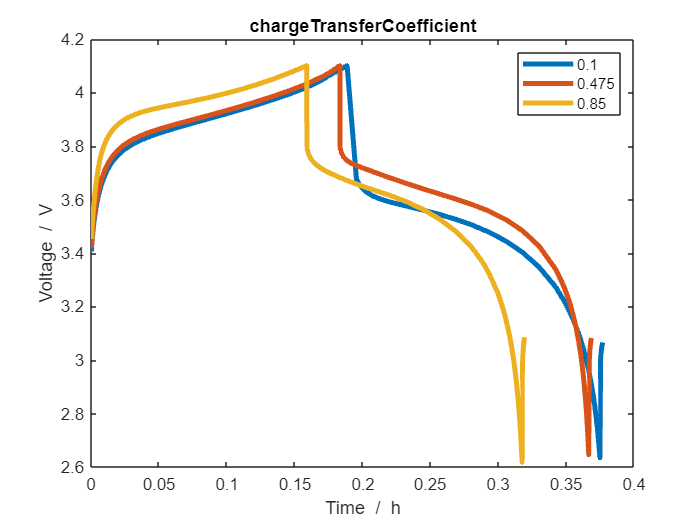

electrode_alpha="NegativeElectrode.";
crate_alpha=3;
kinetic_parameter_2_vals=[linspace(0.1,0.85,3)];
kinetic_parameter_2=strcat(electrode_alpha,"Coating.ActiveMaterial.Interface.chargeTransferCoefficient");
plot_voltage_cccv(kinetic_parameter_2_vals,kinetic_parameter_2,crate_alpha)

#### **Example 7. **Reaction rate constant at the surface of the active particles (exchange current density) - Butler Volmer equation  

The reaction rate constant determines the exchange current density, which in turn influences both the charging and discharging rates of an electrochemical cell. When the exchange current density is large, a significant current can be achieved with only a small overpotential. As we increase the reaction rate constant, we observe a decrease in the cell overpotential for both the positive and negative electrodes, indicating more efficient electrochemical reactions and improved cell performance.

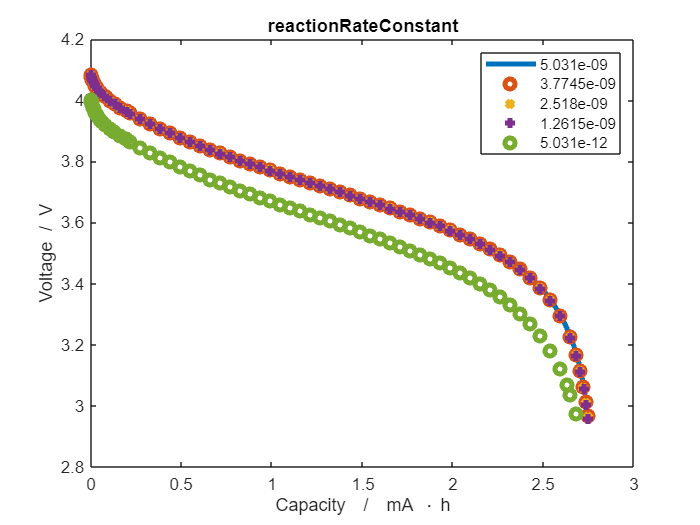

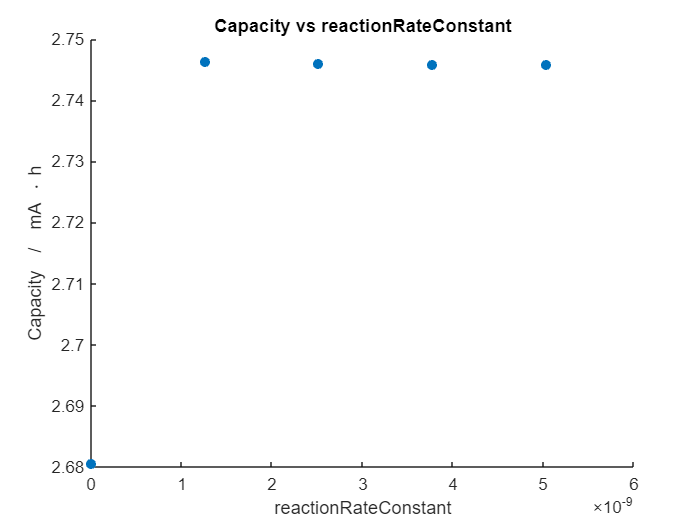

electrode_k="PositiveElectrode.";
crate_k=3;
kinetic_parameter_3=strcat(electrode_k,"Coating.ActiveMaterial.Interface.reactionRateConstant");
kinetic_parameter_3_vals=[linspace(5.031e-9,5.031e-12,5)];
plot_capacities(kinetic_parameter_3_vals,kinetic_parameter_3,crate_k)

### 5. Transport parameters

We now turn our attention to the parameters that describe mass transport within the electrolyte and the electrodes. In this analysis, we will keep the kinetic parameters fixed while varying the transport parameters. 

#### **Example 8. **Transference number $$t_+$$ in the electrolyte - mass transport in the electrolyte

The transference number of an ion is defined as the fraction of the total current carried by that specific species in the electrolyte. When we increase the fraction of current carried by $Li^+$ ions in the electrolyte, rather than by the counter ion $PF_6^-$, we can expect to observe a lower overpotential and a higher capacity. This is because the more efficiently the ions are transported to the electrode, the less overpotential is required to drive the electrochemical reaction, as we observe below. However, as with many parameters, increasing it beyond a certain point does not lead to further significant improvements.

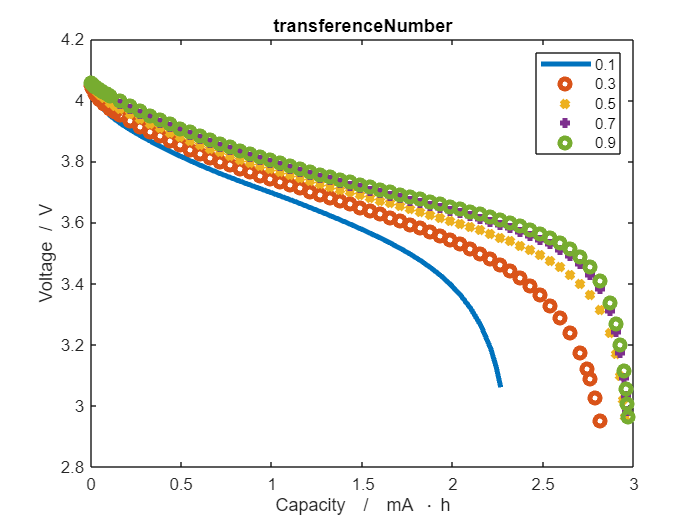

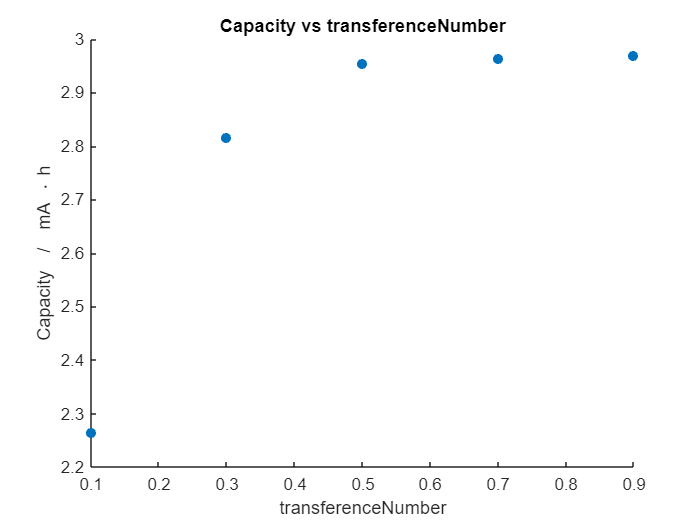

crate_t=3;
kinetic_parameter_5="Electrolyte.species.transferenceNumber";
kinetic_parameter_5_vals=[linspace(0.1,0.9,5)];
plot_capacities(kinetic_parameter_5_vals,kinetic_parameter_5,crate_t)

#### **Example 9. **Active particle radius - mass transport in the electrode (Solid diffusion)

The active particle size plays a crucial role in diffusion within the solid material. A smaller particle size allows for faster diffusion or shorter path, which in turn enables faster charging and discharging, resulting in higher power density. However, this comes at the cost of lower energy density and potentially shorter cycling lifetimes. The increased surface area associated with smaller particles leads to more interactions with the electrolyte, which can accelerate degradation processes and negatively impact the long-term stability of the battery.

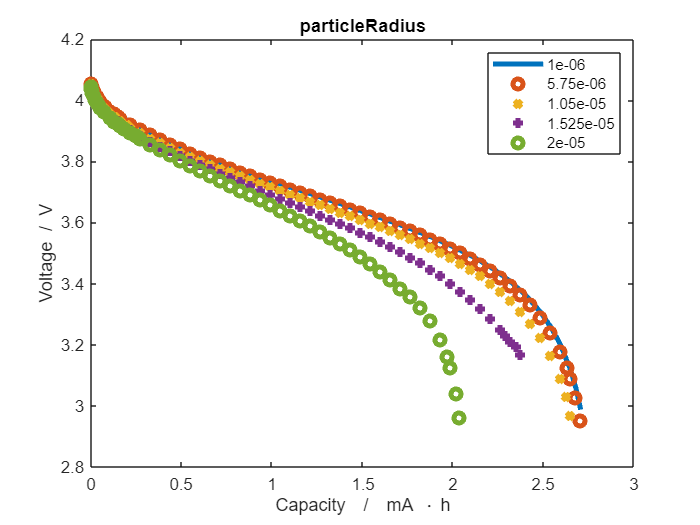

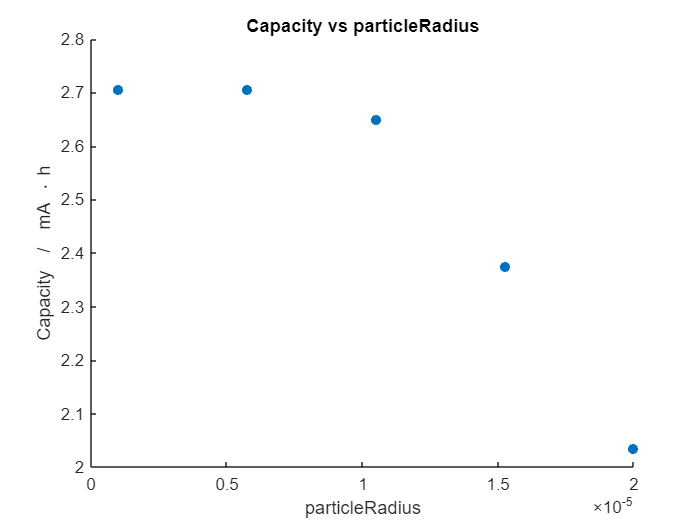

electrode_rad="NegativeElectrode.";
crate_radius=3;
transport_parameter_1=strcat(electrode_rad,"Coating.ActiveMaterial.SolidDiffusion.particleRadius");
transport_parameter_1_vals=[linspace(1,20,5)].*micro;
plot_capacities(transport_parameter_1_vals,transport_parameter_1,crate_radius)

#### **Example 10. **Bruggeman Coefficient in the electrodes- effective electronic conductivity

The Bruggemann coefficient determines the effective electronic conductivity within the electrodes, as well as the ionic conductivity and the effective diffusion coefficient within the electrolyte. This coefficient accounts for the tortuosity and porosity of the material, influencing how easily electrons and ions can move through the porous structure of the electrodes and the electrolyte. This coefficient is influenced by factors such as slurry preparation, drying, and coating processes, which affect the morphology and microstructure of the material. A higher Bruggemann coefficient indicates greater tortuosity, leading to increased difficulty in ion and electron transport, impacting the overall performance of the cell.

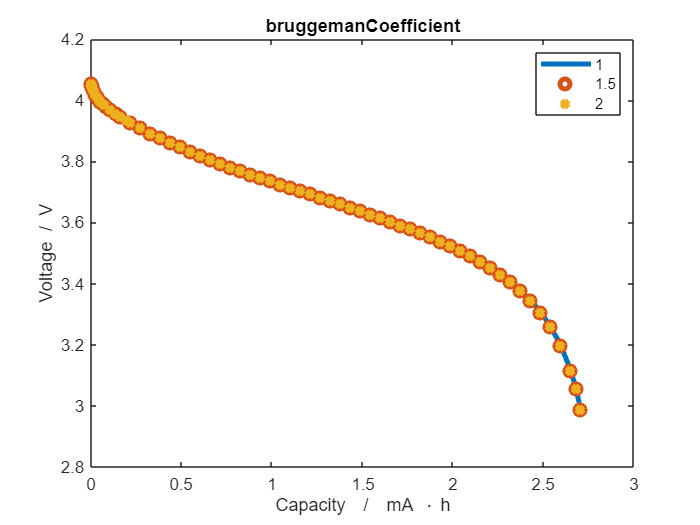

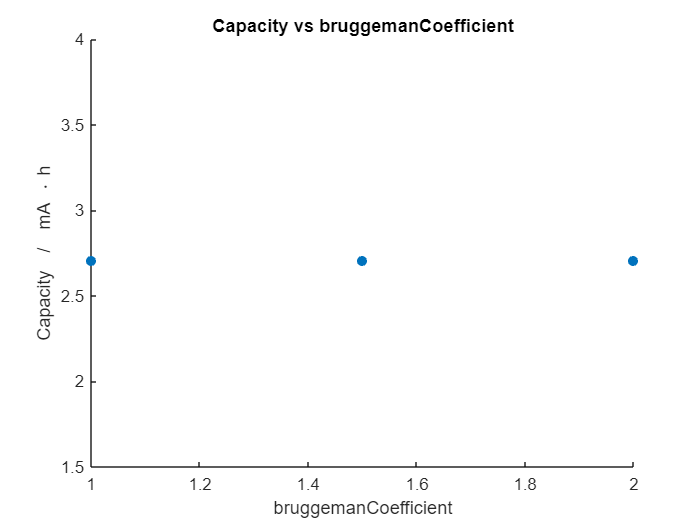

electrode_brug="NegativeElectrode.";
electrode_crate_brug=3;
transport_parameter_4=strcat(electrode_brug,"Coating.bruggemanCoefficient");% does not seem to affect the discharge profile
transport_parameter_4_vals=[linspace(1.0,2,3)];
plot_capacities(transport_parameter_4_vals,transport_parameter_4,electrode_crate_brug)

#### Example 11. Bruggeman Coefficient in the electrolyte-effective diffusion coefficient and ionic conductivity of electrolyte in the electrode region

We observe that as the Bruggemann coefficient increases from 1 to 2, the overpotential rises steeply, accompanied by a loss in capacity.

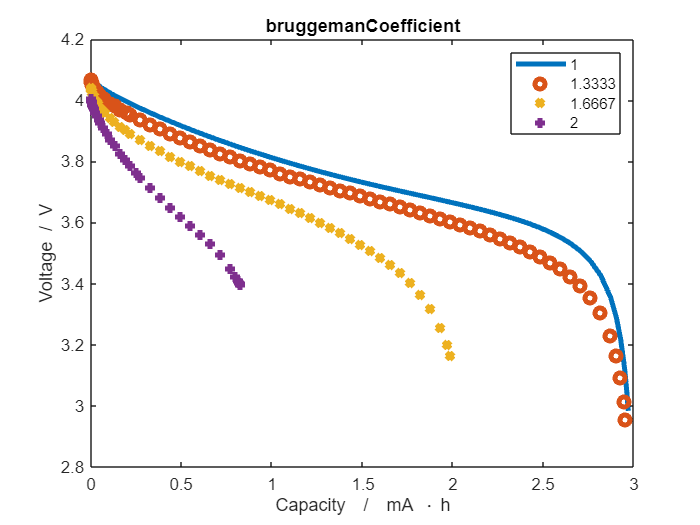

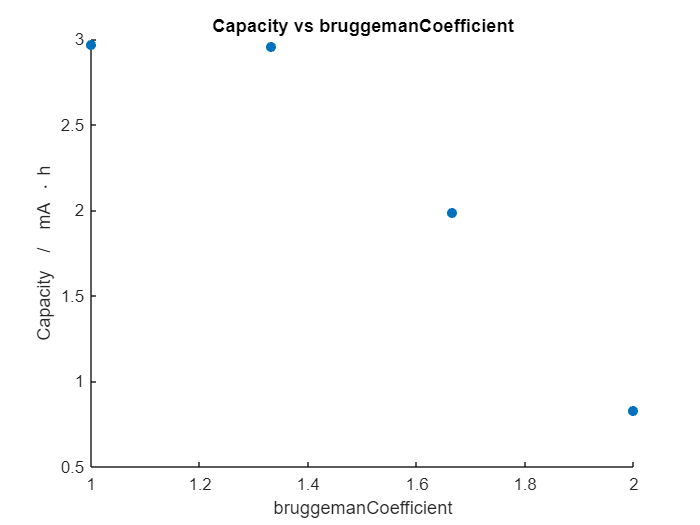

elyte_crate_brug=3;
transport_parameter_5="Electrolyte.bruggemanCoefficient"; % does not seem to affect the discharge profile
transport_parameter_5_vals=[linspace(1.0,2,4)];
plot_capacities(transport_parameter_5_vals,transport_parameter_5,elyte_crate_brug)

#### **Example 12. **Electronic conductivity of the active material in the electrodes

Electronic conductivity plays an important role in determining the potential of the electrodes. Increasing the electronic conductivity should result in a lower overpotential, as it reduces the ohmic resistances within the electrode. Typically, conducting additives are added to enhance this conductivity. However, in this scenario, we are specifically increasing the intrinsic conductivity of the electrodes themselves. This enhancement is expected to lower the overpotential further by reducing internal resistive losses, thereby improving the overall efficiency and performance of the cell.  

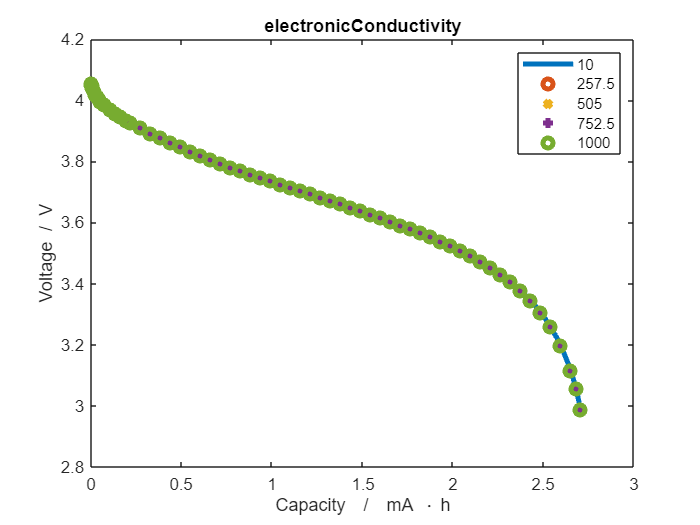

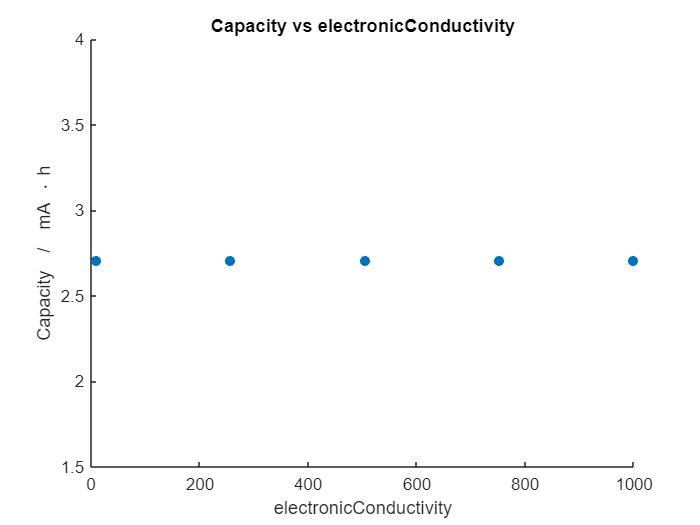

electrode_el_conductivity="NegativeElectrode.";
crate_el_conductivity=3;
transport_parameter_2=strcat(electrode_el_conductivity,"Coating.ActiveMaterial.electronicConductivity");%does not seem to affect the discharge profile
transport_parameter_2_vals=[linspace(10,1000,5)];
plot_capacities(transport_parameter_2_vals,transport_parameter_2,crate_el_conductivity)

#### **Example 13. Initial **Electrolyte concentration- Diffusion Coefficient 

Increasing the concentration of $Li^+$ ions i nitially present in the electrolyte leads to a higher diffusion coefficient, which can enhance the transport of ions and improve the cell performance. However, increasing the concentration beyond a certain point can actually start to decrease the capacity. This occurs because the ionic conductivity of the electrolyte begins to decrease as the electrolyte becomes too concentrated, leading to increased resistance and reduced efficiency in ion transport, ultimately lowering the overall capacity [5].

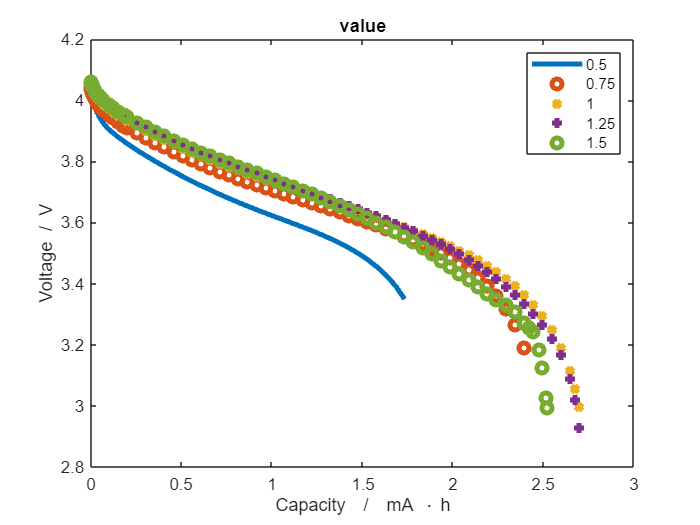

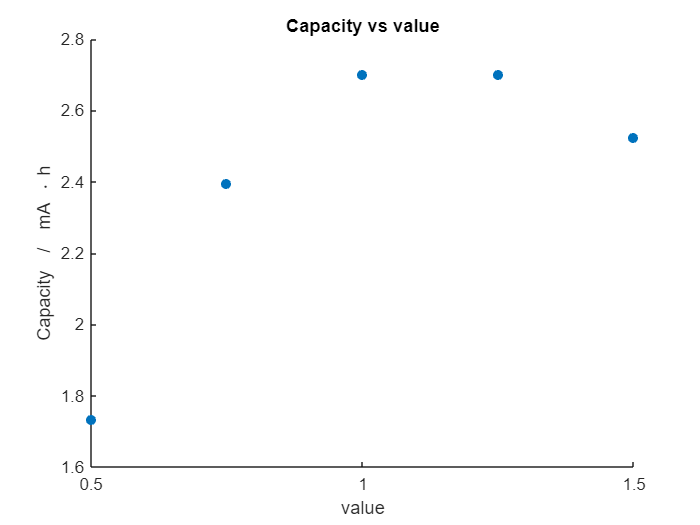

elyte_conc=3;
transport_parameter_3_vals=[linspace(0.5,1.5,5)];
transport_parameter_3="Electrolyte.initialConcentration.value";
plot_capacities(transport_parameter_3_vals,transport_parameter_3,elyte_conc)

**References**

[1][ L. Xia, E. Najafi, Z. Li, H.J. Bergveld, M.C.F. Donkers, "A computationally efficient implementation of a full and reduced-order electrochemistry-based model for Li-ion batteries," *Applied Energy*, vol. 208, pp. 1285-1296, 2017, ISSN 0306-2619](https://www.sciencedirect.com/science/article/pii/S0306261917313090.), [](https://doi.org/10.1016/j.apenergy.2017.09.025.)

[2] [Bharatkumar Suthar, Paul W. C. Northrop, Derek Rife, and Venkat R. Subramanian, "Effect of Porosity, Thickness and Tortuosity on Capacity Fade of Anode," *Journal of The Electrochemical Society*, vol. 162, no. 9, p. A1708, 2015. DOI: 10.1149/2.0061509jes. ](https://iopscience.iop.org/article/10.1149/2.0061509jes)

[3] [Venkat Srinivasan and John Newman, "Discharge Model for the Lithium Iron-Phosphate Electrode," *Journal of The Electrochemical Society*, vol. 151, no. 10, p. A1517, 2004. DOI: 10.1149/1.1785012](https://iopscience.iop.org/article/10.1149/1.1785012/meta).

[4]  [F Brosa Planella *et al* 2022 *Prog. Energy* 4 042003](https://iopscience.iop.org/article/10.1088/2516-1083/ac7d31/meta)

[5] [Sunwook Hwang, Dong-Hui Kim, Jeong Hee Shin, Jae Eun Jang, Kyoung Ho Ahn, Chulhaeng Lee, and Hochun Lee,*The Journal of Physical Chemistry C* **2018** *122* (34), 19438-19446, DOI: 10.1021/acs.jpcc.8b06035](https://pubs.acs.org/doi/10.1021/acs.jpcc.8b06035)

function plot_capacities(parameterArray1,input_parameter1,CRate)
    % Function to take in the specific input parameter along with its
    % values and c-rate and plot the capacities
    %
    % Parameters:
    % parameterArray - a numeric vector
    % input_parameter - a string specifying the operation ('sum', 'mean', 'scale')
    % crate - a numeric value used for scaling (only for 'scale' operation)
    %
    % Returns:
    % None
    % instantiate an empty figure
    capacity_array = [];
    output = cell(size(parameterArray1));
    figure()
    jsonstruct = parseBattmoJson('Examples/JsonDataFiles/sample_input.json'); % load default input
    if nargin == 3
        jsonstruct.Control.CRate = CRate;        
    end
    output = cell(size(parameterArray1));
    markers={'-',"o",'x','+','o','*','x','v','d','^','s','>','<'};
    for i = 1:numel(parameterArray1)
        c = split(input_parameter1,'.');
        jsonstruct = setfield(jsonstruct,c{:},parameterArray1(i));  
        jsonstruct.TimeStepping.totalTime = (1./jsonstruct.Control.CRate) .* 3600 .* 1.1;
        % run the simulation and store the results in the output cell array
        [results,output{i}] = evalc('runBatteryJson(jsonstruct)');
         % retrieve the states from the simulation result
        states = output{i}.states;
        % extract the time and voltage quantities
        time = cellfun(@(state) state.time, states);
        voltage = cellfun(@(state) state.('Control').E, states);
        current = cellfun(@(state) state.('Control').I, states);
        % calculate the capacity
        capacity = time .* current;
        final_capacity=capacity(find(capacity, 1, 'last'))/(hour*milli);
        capacity_array(i)=final_capacity;
        % plot capacity vs voltage
        plot((capacity/(hour*milli)), voltage, markers{i}, 'linewidth', 3);
        xlabel('Capacity  /  mA \cdot h')
        ylabel('Voltage  /  V')
        hold on
        L{i} = strcat(num2str(parameterArray1(i)));
        legend(L);
        title(c{end})
    end
    figure;
    scatter(parameterArray1,capacity_array,"filled")
    ylabel('Capacity  /  mA \cdot h')
    xlabel(c{end})
    title(strcat("Capacity vs ",c{end}));
end

function plot_voltage_cccv(parameterArray1,input_parameter1,CRate)
    % Function to take in the specific input parameter along with its
    % values and c-rate and plot the capacities
    %
    % Parameters:
    % parameterArray - a numeric vector
    % input_parameter - a string specifying the operation ('sum', 'mean', 'scale')
    % crate - a numeric value used for scaling (only for 'scale' operation)
    %
    % Returns:
    % None
    % instantiate an empty figure
    figure()
    output = cell(size(parameterArray1));
    jsonstruct = parseBattmoJson('Examples/JsonDataFiles/sample_input.json'); % load default input            
    cccv_control_protocol = parseBattmoJson('cccv_control_charge.json');%loads the CCCV protocol
    jsonstruct_modified = mergeJsonStructs({cccv_control_protocol, jsonstruct});
    jsonstruct_modified.Control.CRate = CRate;
    output = cell(size(parameterArray1));
    markers={'-',"o",'x','+','o','*','x','v','d','^','s','>','<'};
    for i = 1:numel(parameterArray1)
        c = split(input_parameter1,'.');
        jsonstruct_modified = setfield(jsonstruct_modified,c{:},parameterArray1(i));  
        jsonstruct_modified.TimeStepping.totalTime = (1./jsonstruct_modified.Control.CRate) .* 3600 .* 1.1;
        % run the simulation and store the results in the output cell array
        [results,output{i}] = evalc('runBatteryJson(jsonstruct_modified)');
         % retrieve the states from the simulation result
        states = output{i}.states;
        % extract the time and voltage quantities
        time = cellfun(@(state) state.time, states);
        voltage = cellfun(@(state) state.('Control').E, states);
        current = cellfun(@(state) state.('Control').I, states);
        % calculate the capacity
        capacity = time .* current;
        plot((time/hour), voltage, '-', 'linewidth', 3)
        hold on
        L{i} = strcat(num2str(parameterArray1(i)));
        legend(L);
        title(c{end})
    end
    hold off
   xlabel('Time  /  h')
  ylabel('Voltage  /  V')
end


